phi = [0:2*pi/100:2*pi];
f = @(phi) sin(phi)./phi;
r = f(phi);
r(1) = round(r(2), 3);

subplot(2, 1,1)
line = polarplot(phi, r);
line.LineWidth = 1;
hold on;
c = polarplot(phi(1), r(1), '.');
c.MarkerSize = 19;
c = polarplot(phi(end), r(end), '.');
c.MarkerSize = 19;
c.Color = [0.45, 0.923, 0.28];

hold off;

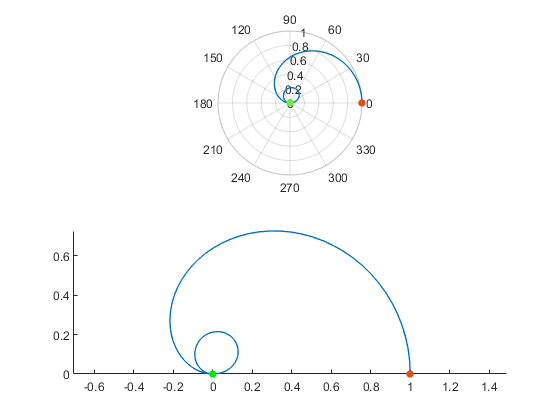

subplot(2, 1,2);
hold on;
axis equal;
[x, y] = pol2cart(phi, r);
line = plot(x, y);
line.LineWidth = 1;
c = plot(x(1), y(1), '.');
c.MarkerSize = 19;
c = plot(x(end), y(end), '.');
c.MarkerSize = 19;
c.Color = [0.0, 0.923, 0.0];

hold off;